# ASTR HW 7 

## PROBLEM 2

clear all
close all
clc

% Assigning the constants for calculation 
% Jupiter
M_j = 1.898*10^27;  % Mass [kg]
r_j = 7.783*10^8;  % Orbital radius [km]
G = 6.67*10^(-20);  % Gravitational constant [km^3/kg^2/s]
P_j = 4*pi^2*r_j^3/G/M_j;  % Period [s]

% Asteroid
P_a = 12*pi^2*r_j^3/5/G/M_j;  % Peroid [s]

## Sketching the two orbits

% Jupiter 
ang_span = linspace(0, 2*pi, 2^15);
R_j = conicEqn(P_j, ang_span, 0.0484);
x_j = R_j.*cos(ang_span);
y_j = R_j.*sin(ang_span);

% Asteroid
R_a = conicEqn(P_a, ang_span, 0);
x_a = R_a.*cos(ang_span);
y_a = R_a.*sin(ang_span);

% Obtaining the minimum eccentricity of atseroid if it intersects with
% Jupiter
[x, fval] = min_eccentricity(0, 0, 0.5);
fprintf('The minimum eccentricity should be: %.6f', x);

The minimum eccentricity should be: 0.436956

fprintf('For this the aphelion is -> %f km', fval);

For this the aphelion is -> 156670580848764256256.000000 km

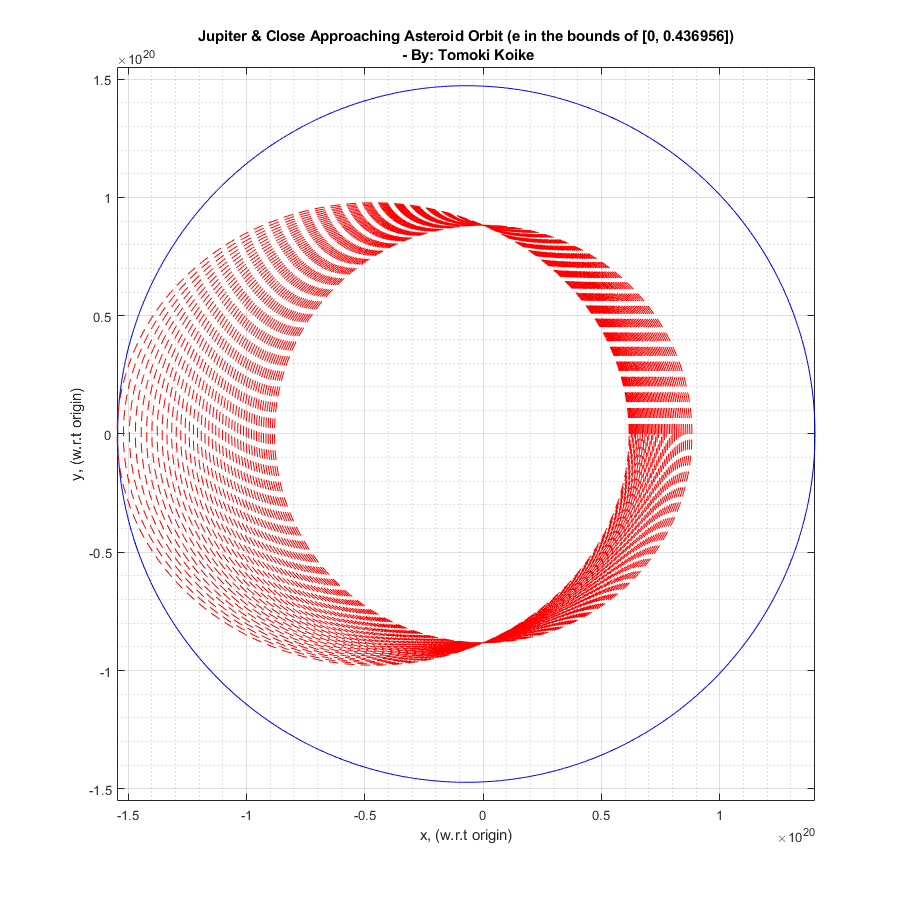


% Plotting
figure('Renderer','painters','Position',[10 10 900 900])
plot(x_j, y_j, '-b', x_a, y_a, '--r')
title({'Jupiter & Close Approaching Asteroid Orbit (e in the bounds of [0, 0.436956])',['' ...
    ' - By: Tomoki Koike']})
xlabel('x, (w.r.t origin)')
ylabel('y, (w.r.t origin)')
hold on
for h = 0:0.01:x
    R_a = conicEqn(P_a, ang_span, h);
    x_a = R_a.*cos(ang_span);
    y_a = R_a.*sin(ang_span);
    plot(x_a, y_a, '--r')
end
hold off
grid on
grid minor
box on
axis equal

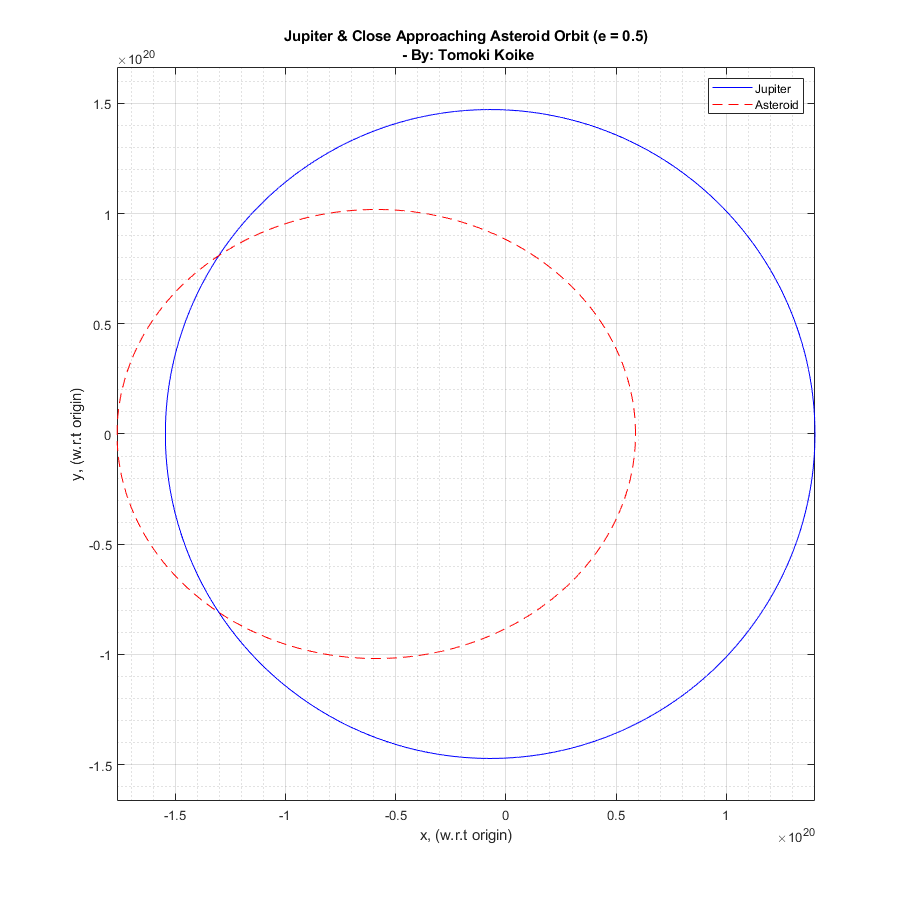


% Say e_asteroid = 0.5 from now on
% Asteroid
R_a = conicEqn(P_a, ang_span, 0.5);
x_a = R_a.*cos(ang_span);
y_a = R_a.*sin(ang_span);
% Plotting
figure('Renderer','painters','Position',[10 10 900 900])
plot(x_j, y_j, '-b', x_a, y_a, '--r')
title({'Jupiter & Close Approaching Asteroid Orbit (e = 0.5)',['' ...
    ' - By: Tomoki Koike']})
xlabel('x, (w.r.t origin)')
ylabel('y, (w.r.t origin)')
grid on
grid minor
box on
axis equal
legend('Jupiter', 'Asteroid')

### FUNCTION

function r = conicEqn(P, ang_span, e)
    % Function to calculate the conic equation 
    r = P ./ (1 + e.*cos(ang_span));
end

function aphelion = cal_aphelion(e, P)
    aphelion = P / (1 - e);
end

function obj = objective(e)
    obj = cal_aphelion(e, 8.82124809062468e+19);
end

function [c, ceq] = constraint(e)
    c = cal_aphelion(0.0484, 1.47020801510411e+20) - cal_aphelion(e, 8.82124809062468e+19);
    ceq = [];
end

function [x,fval,exitflag,output,lambda,grad,hessian] = min_eccentricity(x0,lb,ub)
    %% Start with the default options
    options = optimoptions('fmincon');
    %% Modify options setting
    options = optimoptions(options,'Display', 'off');
    [x,fval,exitflag,output,lambda,grad,hessian] = ...
    fmincon(@objective,x0,[],[],[],[],lb,ub,@constraint,options);
end